close all; clear all;

load('cmap_mat.mat');
%tif_PathName=('C:\Users\noy\Desktop\תזה\ניסויים\Lavi\Lavi_Thermal_RGB\Thermal_transparent_reflectance_grayscale');
%tif_PathName=('C:\Users\noy\Desktop\תזה\ניסויים\Kedma\Kedma_Thermal\Thermal_transparent_reflectance_grayscale');
tif_PathName=('C:\Users\noy\Desktop\תזה\ניסויים\Lavi2\Lavi_Thermal\Thermal_transparent_reflectance_grayscale')

tif_PathName = 'C:\Users\noy\Desktop\תזה\ניסויים\Lavi2\Lavi_Thermal\Thermal_transparent_reflectance_grayscale'

TIR=imread(tif_PathName,"tif");
tfw_file=strcat(tif_PathName,'.tfw');
tfw=worldfileread(tfw_file,'planar',size(TIR));
TIR= double(TIR)/100;
TIR(find(TIR<0.1))=0;
TIR(find(TIR>70))=0;
%histogram(TIR(:),'BinWidth', 0.1,'BinLimits', [20 70],'FaceAlpha',0.5,'EdgeColor','none');
%axis tight
%% open tif file with geographic coordinates


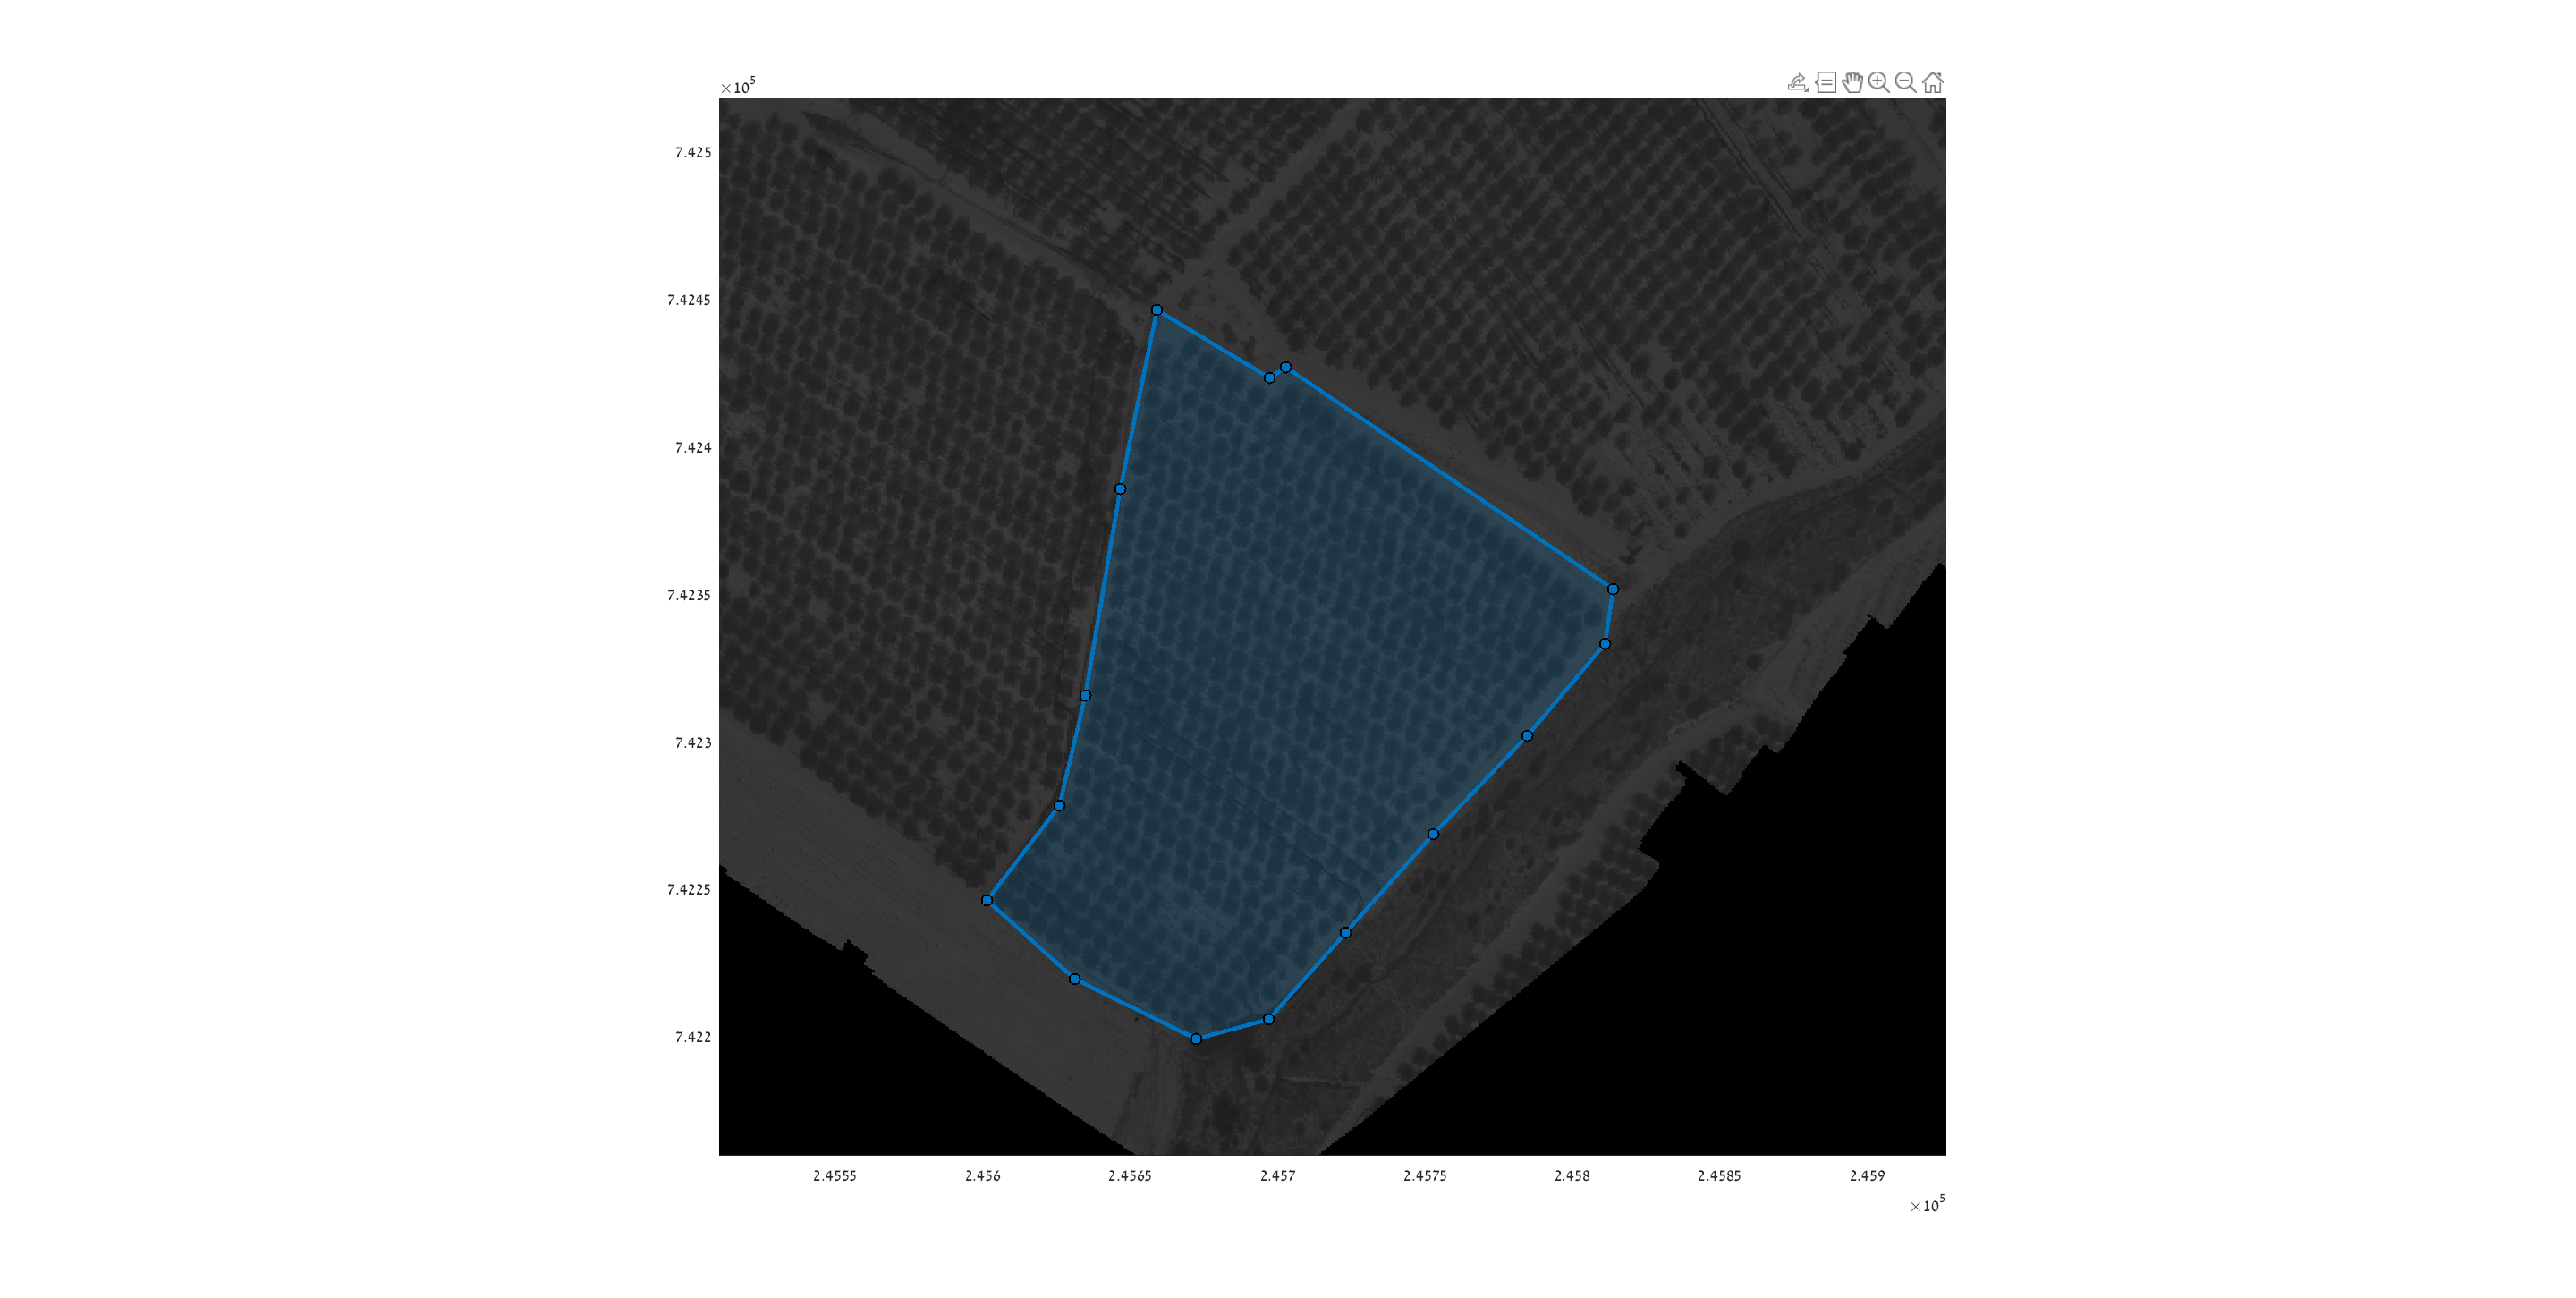

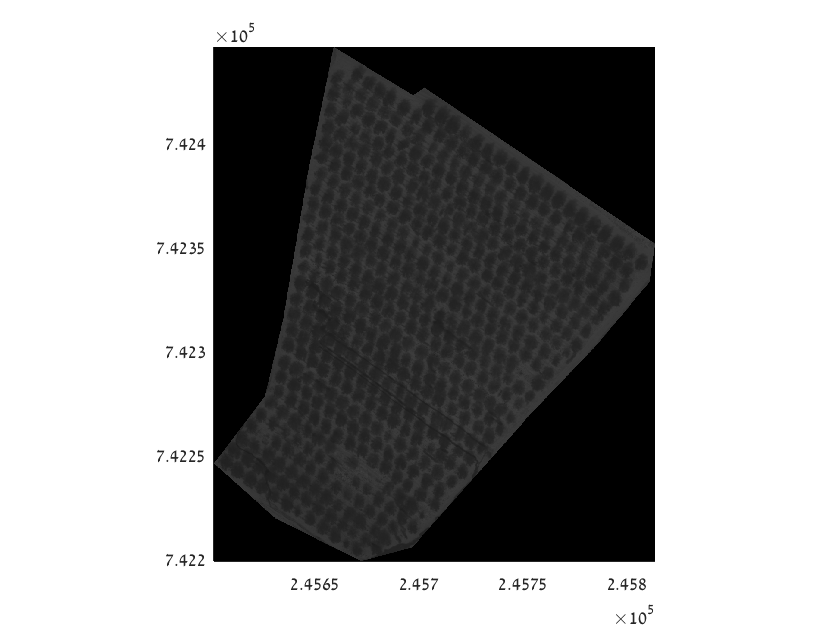

[tir_mask,trim_tfw,corr_vec]=trim_tif_twf(tfw,TIR,tif_PathName);

Name= 'plot_G'

Name = 'plot_G'

save_path='C:\Users\noy\Desktop\תזה\ניסויים\Lavi2\Plots\';
worldfilewrite(trim_tfw, [save_path  Name '.tfw']);
save([save_path  Name '.mat'],'tir_mask');
imwrite(tir_mask, [save_path  Name '.png']);

trim imag

function [tif_mask,trim_tfw,corr_vec]=trim_tif_twf(tfw,tif,tif_PathName)
% trim tif image
h=figure;
mapshow(uint8(tif),tfw);
xlim(tfw.XLimWorld);ylim(tfw.YLimWorld);
hold on
figure(h);
hp = drawpolygon;
pos_map=hp.Position;
[row_pos_pix,col_pos_pix]=map2pix(tfw,pos_map);

X_upper_pix=round(min(col_pos_pix));
Y_upper_pix=round(min(row_pos_pix));
X_lower_pix=round(max(col_pos_pix));
Y_lower_pix=round(max(row_pos_pix));

[X_upper_map,Y_upper_map]=pix2map(tfw,Y_upper_pix,X_upper_pix);
[X_lower_map,Y_lower_map]=pix2map(tfw,Y_lower_pix,X_lower_pix);

min_X_map=min([X_lower_map,X_upper_map]);
max_X_map=max([X_lower_map,X_upper_map]);
min_Y_map=min([Y_lower_map,Y_upper_map]);
max_Y_map=max([Y_lower_map,Y_upper_map]);

corr_vec=[min_X_map max_X_map min_Y_map max_Y_map];

% trim tfw image
trim_tfw =worldfileread([tif_PathName '.tfw']);
trim_tfw(3,1)=X_upper_map;
trim_tfw(3,2)=Y_upper_map;
% worldfilewrite(trim_tfw, 'concord_ortho_w_test.tfw');
BW=createMask(hp);
% tif_mask=tif.*uint16(repmat((BW),[1 1 3]));
tif_mask=tif.*BW;
tif_mask=tif_mask(Y_upper_pix:Y_lower_pix,X_upper_pix:X_lower_pix,:);
% show trimed tif image with trimed tfw
h1=figure;
figure(h1);
mapshow(uint8(tif_mask),trim_tfw);
end
